clear; clc;

% --- Parameters ---
data_folder = '/Users/manoharpaturi/Desktop/EEE S2 Proj/TestCasesLibrary_Measurement/Forced oscillation/Case 1F';
dt = 40 / 1200; % Time step (s)
expected_gens = 29; % Expected number of generators
fixed_rank = 29; % Force 29 modes
reg_param = 1e-2; % Regularization parameter for DMD

% --- Load Data ---
[Xraw, num_gens] = load_data(data_folder, dt);

Raw data size for rotor_speeds.csv: 1201 rows, 29 columns
Loaded rotor_speeds.csv: 1201 rows, 29 columns
Raw data size for rotor_angles.csv: 1201 rows, 29 columns
Loaded rotor_angles.csv: 1201 rows, 29 columns
Final Xraw: 29 signals, 2402 time steps


if num_gens ~= expected_gens
    error('Number of generators (%d) does not match expected (%d).', num_gens, expected_gens);
end
fprintf('Number of generators: %d\n', num_gens);

Number of generators: 29



% --- Prepare DMD Inputs ---
Xraw = Xraw - mean(Xraw, 2);
X1 = Xraw(:, 1:end-1);
X2 = Xraw(:, 2:end);
t = (0:size(Xraw, 2)-1) * dt;

% --- Rank Selection ---
[U, S, V] = svd(X1, 'econ');
singular_values = diag(S);
r = min(fixed_rank, length(singular_values));
if r < fixed_rank
    warning('Only %d singular values available; using rank %d.', length(singular_values), r);
end
fprintf('Selected rank for DMD: %d\n', r);

Selected rank for DMD: 29



--- Optimized DMD ---


Reconstruction Error: 9.246092e-01


Modes (29 total):


    frequency     damping_ratio      energy      amplitude     dominant_generator
    __________    _____________    __________    __________    __________________

             0              1      1.7542e-05     0.0041883            16        
             0              1       0.0002167      0.014721            16        
    9.2855e-08              1           26218        161.92            16        
       0.10882         0.3819        0.011353       0.10655            23        
       0.10882         0.3819        0.011353       0.10655            23        
       0.36173        0.15492       0.0004431       0.02105            16        
       0.36173        0.15492       0.0004431       0.02105            16        
        0.3766       0.004061      8.7604e-05     0.0093597            23        
        0

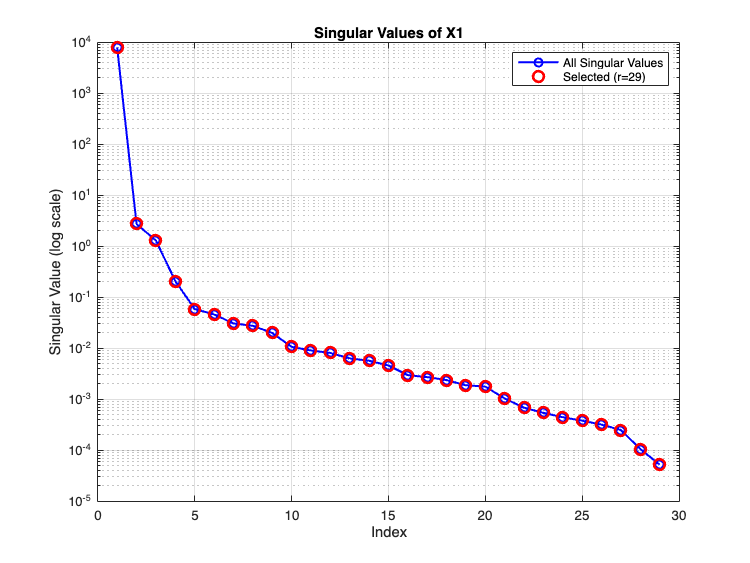

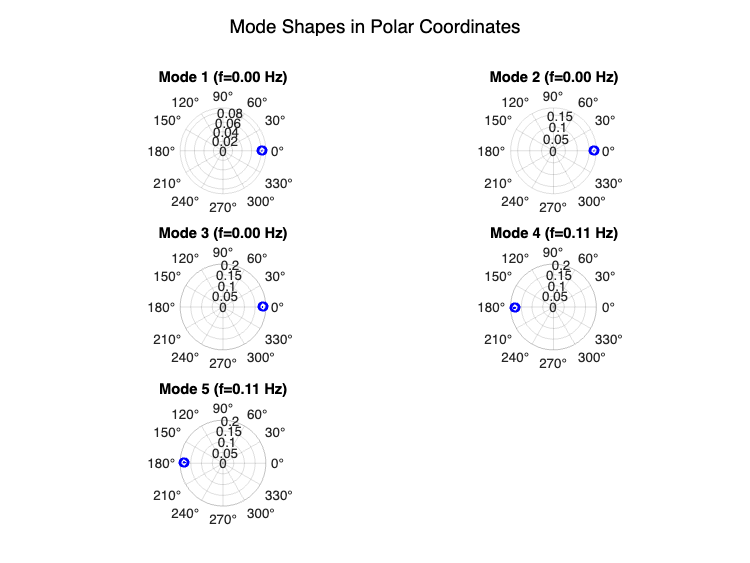

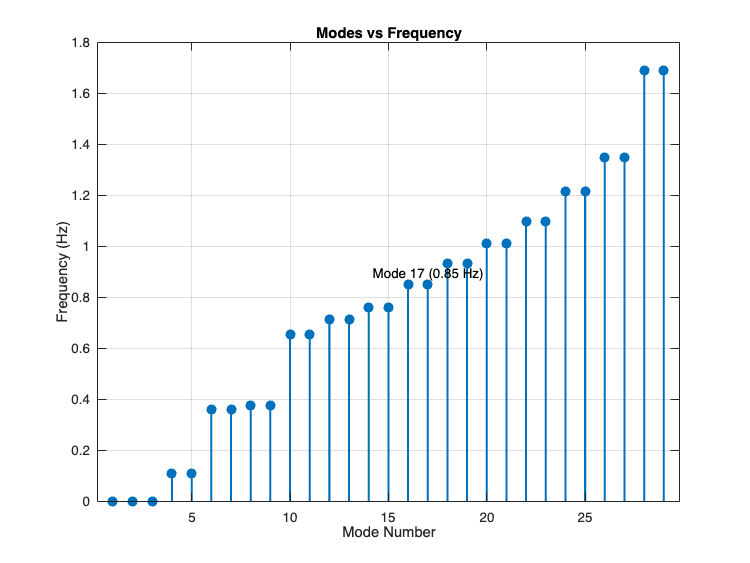


% --- Optimized DMD ---
try
    [Phi_opt, lambda_opt, freq_opt, damping_opt, b_opt] = compute_opt_dmd(Xraw, r, dt, reg_param);
    assert(size(Phi_opt, 2) == length(b_opt), 'Optimized DMD: Phi and b dimensions mismatch');
    assert(length(b_opt) == length(lambda_opt), 'Optimized DMD: b and lambda dimensions mismatch');
    X_recon_opt = zeros(size(Xraw));
    for k = 1:length(t)
        X_recon_opt(:, k) = real(Phi_opt * (b_opt .* exp(log(lambda_opt) * t(k))));
    end
    error_opt = norm(Xraw - X_recon_opt, 'fro') / norm(Xraw, 'fro');
    mode_props_opt = analyze_modes(Phi_opt, lambda_opt, freq_opt, damping_opt, b_opt, num_gens);
catch e
    fprintf('Error in Optimized DMD: %s\n', e.message);
    error_opt = NaN;
    mode_props_opt = [];
end

% --- Display Modes ---
if ~isnan(error_opt)
    fprintf('\n--- Optimized DMD ---\n');
    fprintf('Reconstruction Error: %.6e\n', error_opt);
    fprintf('Modes (%d total):\n', height(mode_props_opt));
    dominant_gen = zeros(height(mode_props_opt), 1);
    for j = 1:height(mode_props_opt)
        mode_shape = mode_props_opt.mode_shape{j}(1:num_gens);
        participation = calc_participation(mode_shape, num_gens);
        [~, max_gen] = max(participation);
        dominant_gen(j) = max_gen;
    end
    mode_props_opt.dominant_generator = dominant_gen;
    disp(mode_props_opt(:, {'frequency', 'damping_ratio', 'energy', 'amplitude', 'dominant_generator'}));
    
    % --- Plotting ---
    % Singular Values Plot
    figure;
    semilogy(singular_values, 'bo-', 'LineWidth', 1.5);
    hold on;
    semilogy(singular_values(1:r), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    title('Singular Values of X1', 'FontSize', 14);
    xlabel('Index', 'FontSize', 12);
    ylabel('Singular Value (log scale)', 'FontSize', 12);
    legend('All Singular Values', sprintf('Selected (r=%d)', r));
    grid on;
    set(gca, 'FontSize', 10);
    
    % Mode Shapes in Polar Coordinates (first few modes)
    num_modes_to_plot = min(5, height(mode_props_opt)); % Plot up to 5 modes
    figure;
    for j = 1:num_modes_to_plot
        subplot(ceil(num_modes_to_plot/2), 2, j);
        mode_shape = mode_props_opt.mode_shape{j}(1:num_gens);
        theta = angle(mode_shape); % Phase in radians
        rho = abs(mode_shape); % Magnitude
        polarplot(theta, rho, 'bo-', 'LineWidth', 1.5);
        title(sprintf('Mode %d (f=%.2f Hz)', j, mode_props_opt.frequency(j)), 'FontSize', 10);
        pax = gca;
        pax.ThetaAxisUnits = 'degrees';
        pax.FontSize = 10;
    end
    sgtitle('Mode Shapes in Polar Coordinates', 'FontSize', 14);
    
    % Modes vs Frequency Plot
    figure;
    mode_numbers = 1:height(mode_props_opt);
    stem(mode_numbers, mode_props_opt.frequency, 'filled', 'LineWidth', 1.5, 'MarkerSize', 6);
    title('Modes vs Frequency', 'FontSize', 14);
    xlabel('Mode Number', 'FontSize', 12);
    ylabel('Frequency (Hz)', 'FontSize', 12);
    grid on;
    % Label the mode closest to 0.86 Hz
    [~, idx_086] = min(abs(mode_props_opt.frequency - 0.86));
    text(mode_numbers(idx_086), mode_props_opt.frequency(idx_086)*1.05, ...
         sprintf('Mode %d (%.2f Hz)', idx_086, mode_props_opt.frequency(idx_086)), ...
         'FontSize', 10, 'HorizontalAlignment', 'center');
    set(gca, 'FontSize', 10);
else
    fprintf('\n--- Optimized DMD ---\n');
    fprintf('Failed to compute modes.\n');
end


% --- Helper Functions ---

function [Xraw, num_gens] = load_data(data_folder, dt)
    file_names = {'rotor_speeds.csv', 'rotor_angles.csv'};
    Xraw = [];
    num_gens = 0;
    
    for i = 1:length(file_names)
        file_path = fullfile(data_folder, file_names{i});
        if exist(file_path, 'file')
            data = readmatrix(file_path, 'NumHeaderLines', 1);
            if size(data, 2) < 2
                warning('File %s has insufficient columns.', file_names{i});
                continue;
            end
            data = data(:, 2:end);
            fprintf('Raw data size for %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
            if contains(file_names{i}, 'rotor_speeds', 'IgnoreCase', true)
                num_gens = size(data, 2);
                mean_spd = mean(data(:));
                if mean_spd < 1
                    warning('Rotor speeds appear to be in per-unit (mean = %.4f). Converting to Hz assuming 60 Hz base.', mean_spd);
                    data = data * 60;
                end
            else
                max_val = max(abs(data(:)));
                if max_val > 0
                    data = data / max_val;
                else
                    data = zeros(size(data));
                end
            end
            Xraw = [Xraw; data];
            fprintf('Loaded %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
        else
            warning('File %s not found.', file_path);
        end
    end
    
    if isempty(Xraw)
        error('No data loaded.');
    end
    
    Xraw = Xraw';
    fprintf('Final Xraw: %d signals, %d time steps\n', size(Xraw, 1), size(Xraw, 2));
end

function [Phi, lambda, freq_Hz, damping_ratio, b] = compute_opt_dmd(X, r, dt, reg_param)
    X1 = X(:, 1:end-1);
    X2 = X(:, 2:end);
    
    [U, S, V] = svd(X1, 'econ');
    U_r = U(:, 1:r); S_r = S(1:r, 1:r); V_r = V(:, 1:r);
    A_tilde = U_r' * X2 * V_r / S_r;
    A_tilde_reg = A_tilde + reg_param * eye(size(A_tilde));
    [W, D] = eig(A_tilde_reg);
    lambda = diag(D);
    Phi = X2 * V_r / S_r * W;
    b = pinv(Phi) * X1(:, 1);
    
    t = (0:size(X, 2)-1) * dt;
    lambda_init = log(lambda) / dt;
    b_init = b;
    
    function err = objective(params)
        lambda_opt = params(1:r) + 1i * params(r+1:2*r);
        b_opt = params(2*r+1:3*r) + 1i * params(3*r+1:4*r);
        X_recon = zeros(size(X));
        for k = 1:length(t)
            X_recon(:, k) = real(Phi * (b_opt .* exp(lambda_opt * t(k))));
        end
        err = norm(X_recon - X, 'fro')^2;
    end
    
    options = optimoptions('fminunc', 'Display', 'off', 'MaxIterations', 50);
    params_init = [real(lambda_init); imag(lambda_init); real(b_init); imag(b_init)];
    try
        params_opt = fminunc(@objective, params_init, options);
    catch
        warning('Optimization failed; returning initial DMD results.');
        params_opt = params_init;
    end
    
    lambda_opt = params_opt(1:r) + 1i * params_opt(r+1:2*r);
    b = params_opt(2*r+1:3*r) + 1i * params_opt(3*r+1:4*r);
    lambda = exp(lambda_opt * dt);
    
    omega = lambda_opt;
    freq_Hz = abs(imag(omega)) / (2 * pi);
    abs_omega = abs(omega);
    damping_ratio = zeros(size(omega));
    valid = abs_omega > 1e-6;
    damping_ratio(valid) = -real(omega(valid)) ./ abs_omega(valid);
    damping_ratio(~valid) = 0;
end

function mode_props = analyze_modes(Phi, lambda, freq_Hz, damping_ratio, b, num_gens)
    num_modes = length(lambda);
    mode_energy = abs(b).^2;
    amplitude = abs(b); % Amplitude is the magnitude of b
    
    mode_shapes = cell(num_modes, 1);
    for i = 1:num_modes
        mode_shapes{i} = Phi(:, i);
    end
    
    mode_props = table(...
        freq_Hz(:), damping_ratio(:), mode_energy(:), amplitude(:), mode_shapes, ...
        'VariableNames', {'frequency', 'damping_ratio', 'energy', 'amplitude', 'mode_shape'});
    
    mode_props = sortrows(mode_props, 'frequency');
end

function participation = calc_participation(mode_shape, num_gens)
    if length(mode_shape) < num_gens
        error('Mode shape length (%d) less than num_gens (%d).', length(mode_shape), num_gens);
    end
    mode = mode_shape(1:num_gens);
    norm_val = norm(mode);
    if norm_val > 1e-6
        normalized = mode / norm_val;
    else
        normalized = zeros(size(mode));
    end
    participation = abs(normalized).^2;
end